# Nearest neighbor classification

clear; close all force; clc
% change directory in order for relative references to work
cd(fileparts(matlab.desktop.editor.getActiveFilename))

We have a look at the nearest neighbor classification for supervised learning. The following topics will be adressed:

- the principle

- hyperparameter tuning

- distance metrics

- application

## Principle 

Below you have some randomly generated points. We want to classify these using nearest neigbor classification

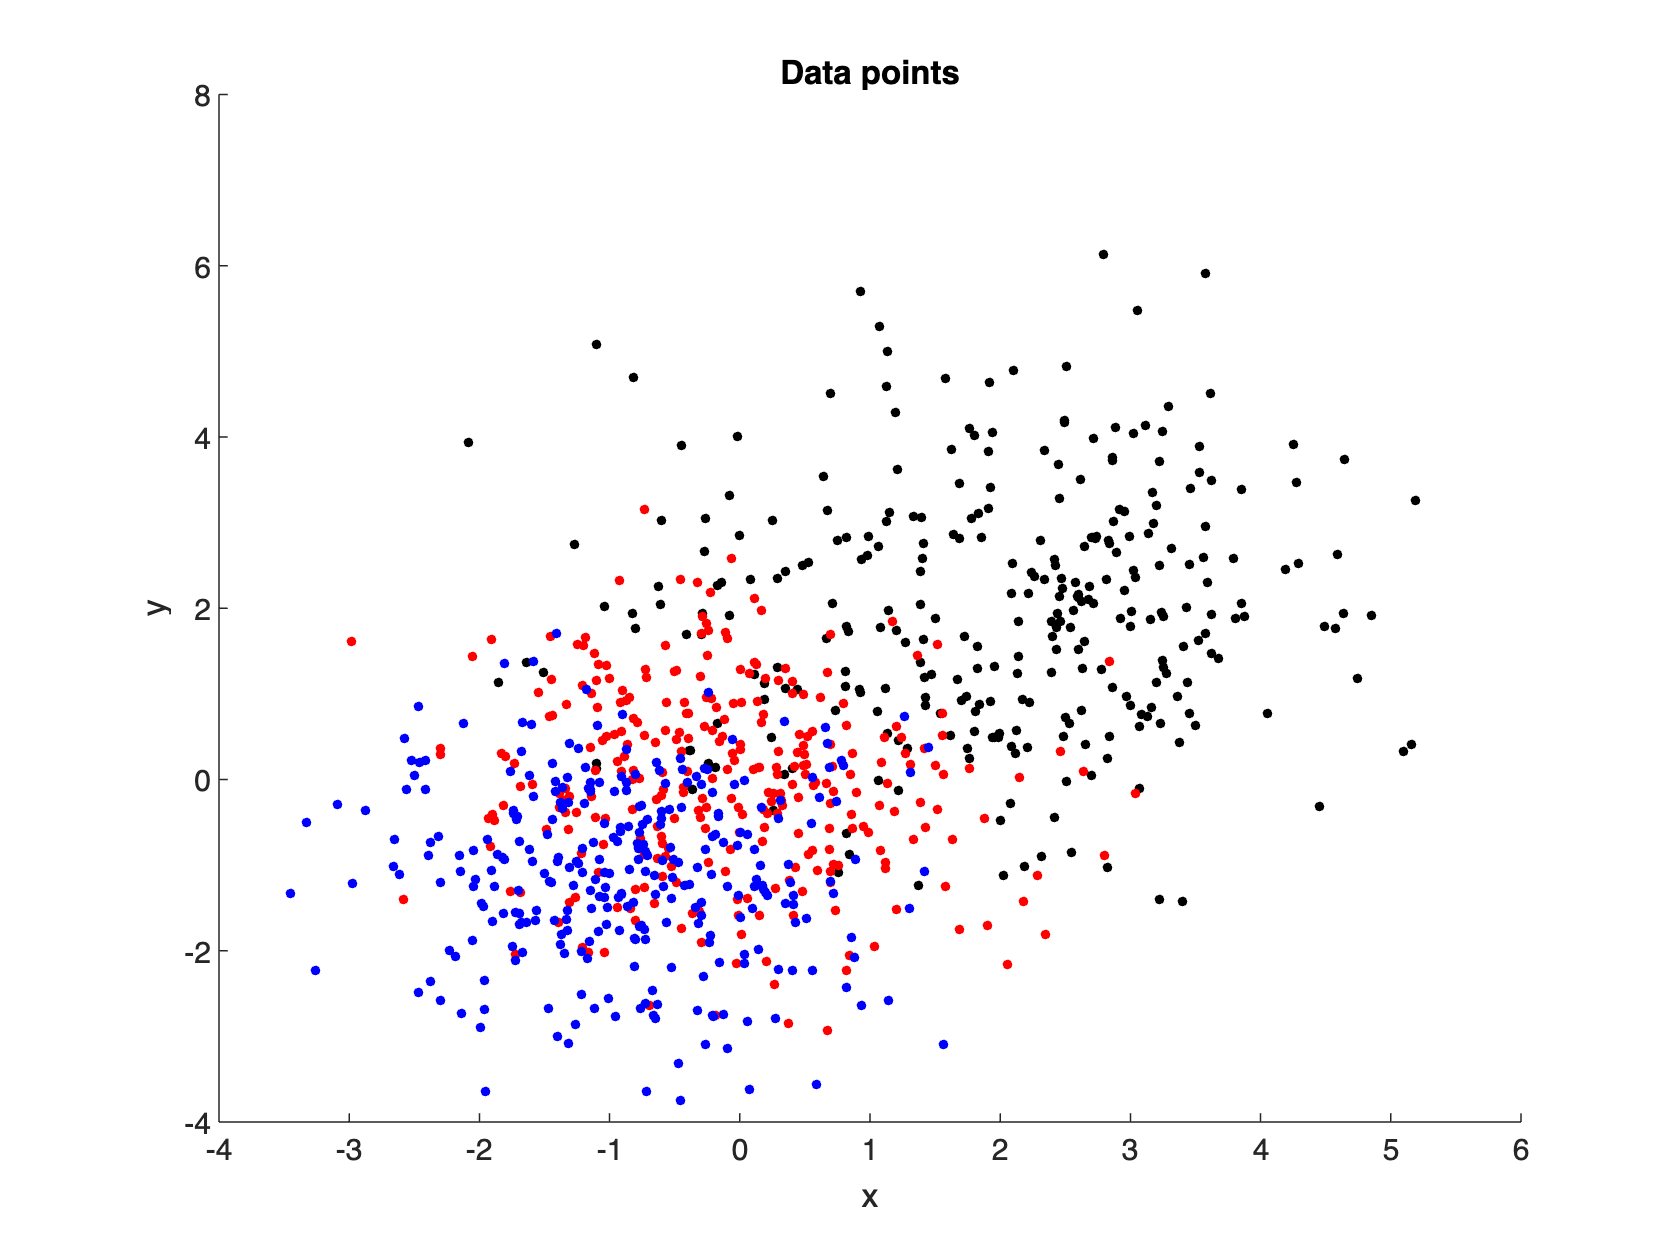

ncat = 300;
x = [mvnrnd([2 2],[2 0;0 2],ncat);...
    mvnrnd([0 0],[1 0;0 1],ncat);...
    mvnrnd([-1 -1],[1 0;0 1],ncat)];
y = [ones(ncat,1); 2*ones(ncat,1);3*ones(ncat,1)];
y = categorical(y,[1 2 3],["Cat A" "Cat B" "Cat C"]); % make it a categorical variable
% color matrix (for plotting)
col = [repmat([0 0 0],ncat,1);...
    repmat([1 0 0],ncat,1);...
    repmat([0 0 1],ncat,1)];
% figure
scatter(x(:,1),x(:,2),10,col,'filled')
title('Data points'); xlabel('x'); ylabel('y')

model = fitcknn(x,y)

model =   ClassificationKNN
             ResponseName: 'Y'
    CategoricalPredictors: []
               ClassNames: [Cat A    Cat B    Cat C]
           ScoreTransform: 'none'
          NumObservations: 900
                 Distance: 'euclidean'
             NumNeighbors: 1


  Properties, Methods


When you don't specify any options, you can see that the model uses euclidean distance and one neighbor by default

model.loss(x, y)

ans = 0

Again, to avoid overfitting, we work with crossvalidation.

% Split data in training and testing
c = cvpartition(y,"KFold",10);
cvmodel = crossval(model,'CVPartition', c);
kfoldLoss(cvmodel)

ans = 0.3500

## Hyperparameter tuning

Although our model works, it does not perform really well. Let's improve this by finding the optimal value for the hyperparameter k in k-nearest neigbors.

You can select optimal machine learning hyperparameters using Bayesian optimization (using the bayesopt instruction).

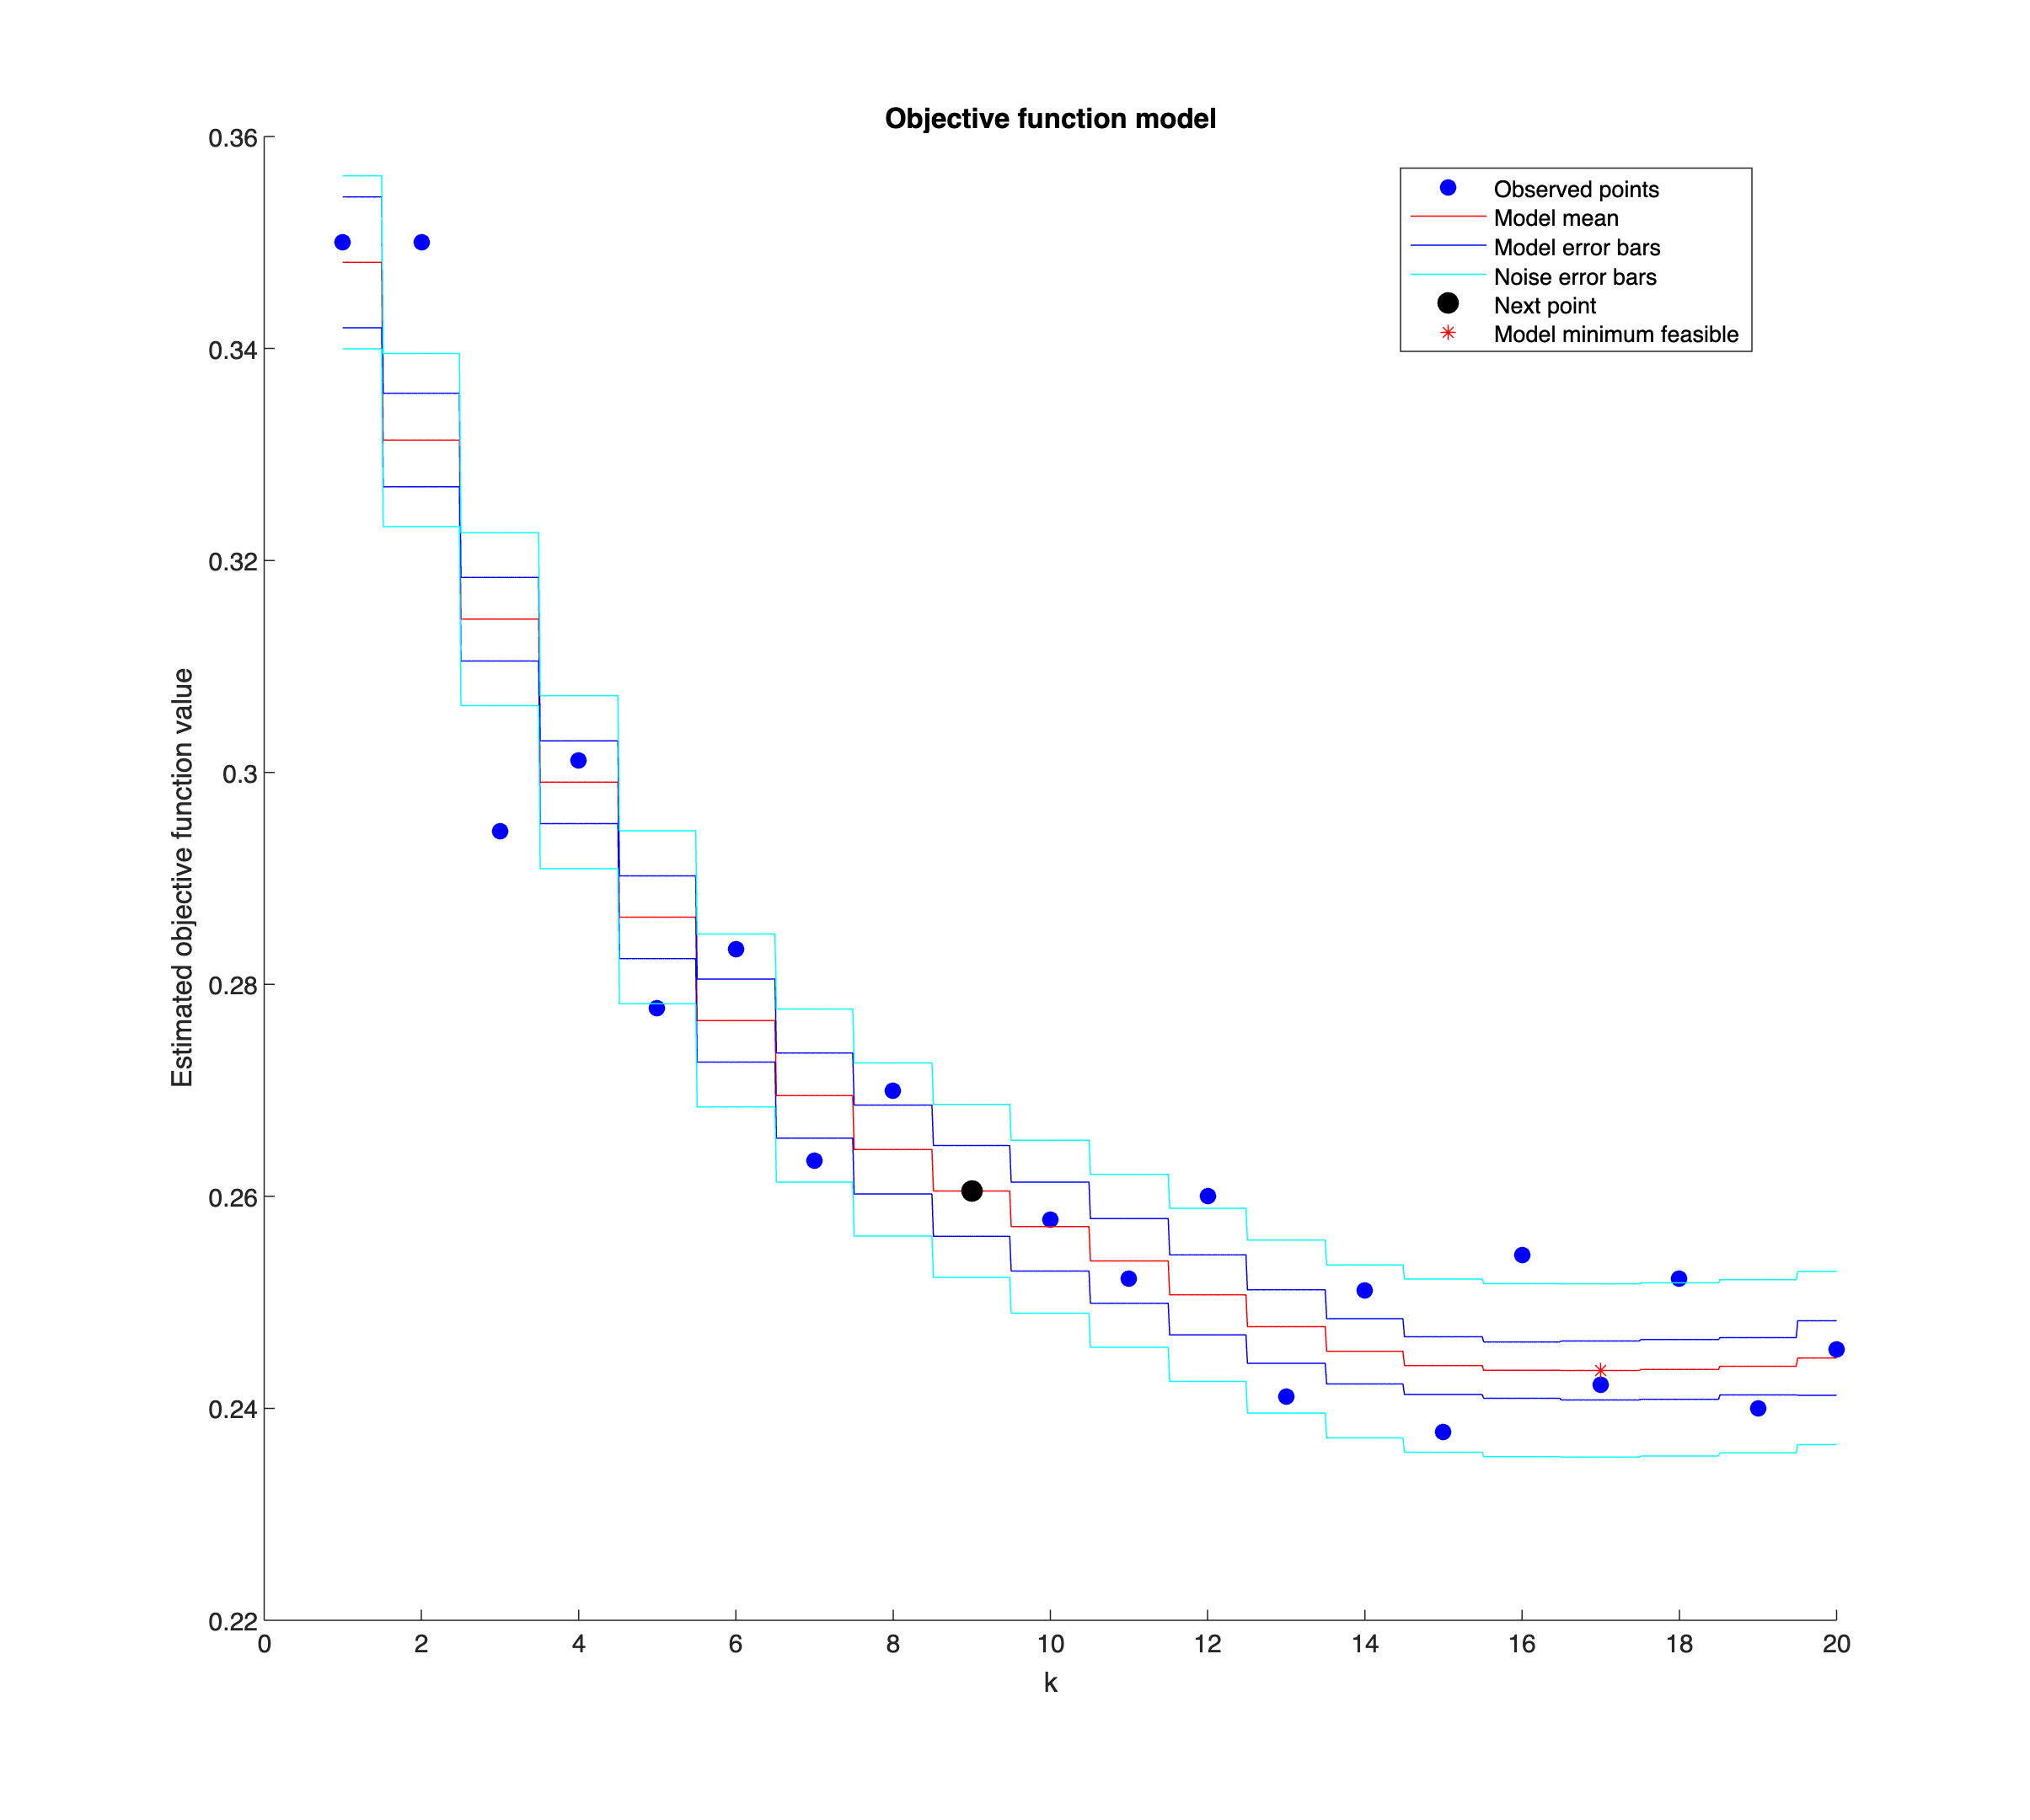

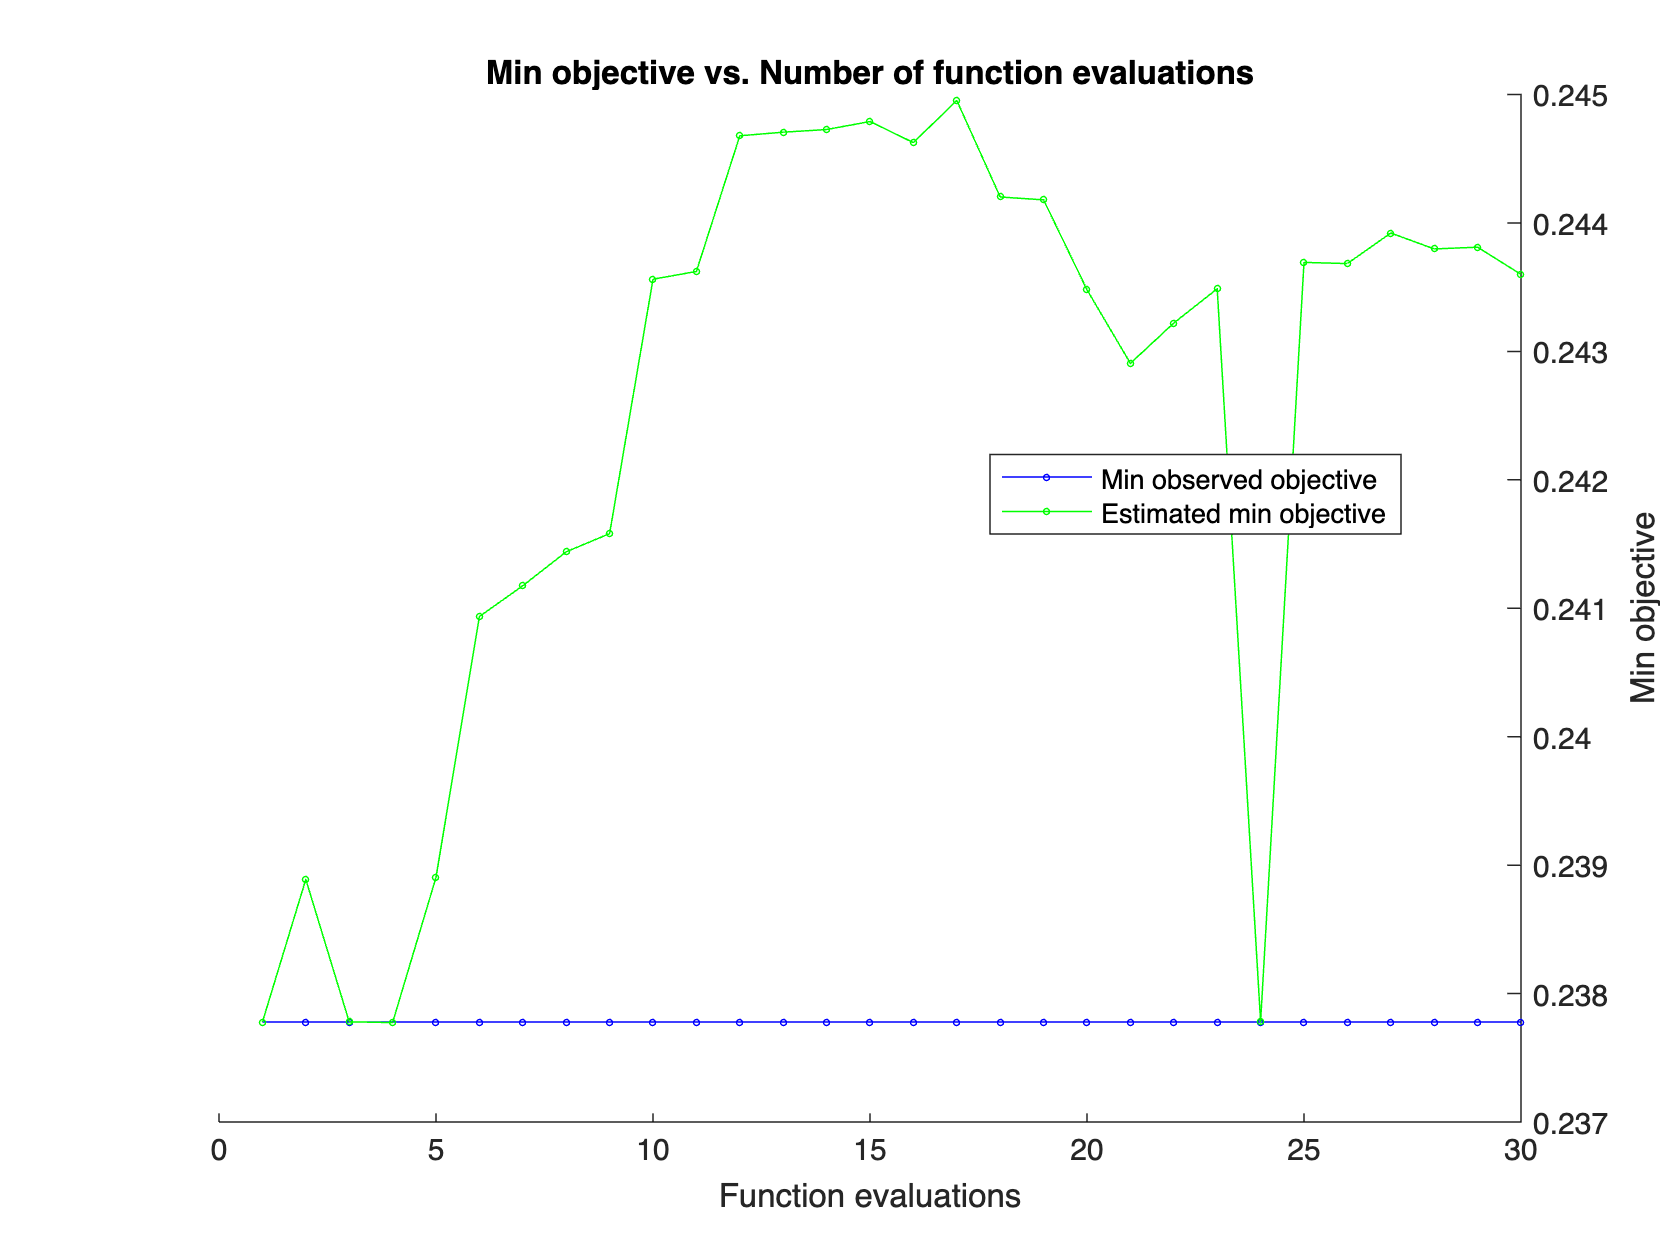

% set k as one of the hyperparameters (integer in the range 1 -> 20)
k = optimizableVariable('k',[1, 20], 'Type',"integer");
% function to optimise (i.e. find k that minimises the loss)
f = @(v) kfoldLoss(fitcknn(x,y,'CVPartition',c,'NumNeighbors',v.k));
% actual optimisation
res = bayesopt(f,k,"Verbose",0);

res.XAtMinObjective

ans = table
    k 
    __

    15


## Distance metrics

In the previous application we have used the euclidean distance by default. There are a lot of additional distance metrics availble to use in combination with k-NN classification. Most common metrics are already available, but you can define your own distance metric as well.

## Number recognition

clear; close all force; clc

We want to automate handwritten number recognition. The MNIST dataset is one of the most common datasets used for image classification. In this dataset, each line represents a digit. The label (0-9) corresponds with the digits. Each of the 784 columns corresponds to one pixel of a 28x28 pixels image that was scanned. The value of each pixels is in the range [0-255] and gives you the grayscale intensity of the pixel.

Given the dimensionality of the problem and the large amount of entries (42e3), we wil only use a subset for faster computation. For a production setting, you will probably want to use all available data.

D = readtable('./datasets/MNIST-train.csv');
% modify datatype
D.label = categorical(D.label);
% use only 10% of data for training
part = cvpartition(D.label,"HoldOut", 0.9, "Stratify", true);

Note that we used stratified sampling, so each subset of the data will contain the same ratio of classes as the global dataset.

% limit data for training
d = D(part.training,:);
% data for testing (limit to 1k entries)
t = D(part.test,:);
t = t(1:1000,:);
% quick look into data
head(d)

    label    pixel0    pixel1    pixel2    pixel3    pixel4    pixel5    pixel6    pixel7    pixel8    pixel9    pixel10    pixel11    pixel12    pixel13    pixel14    pixel15    pixel16    pixel17    pixel18    pixel19    pixel20    pixel21    pixel22    pixel23    pixel24    pixel25    pixel26    pixel27    pixel28    pixel29    pixel30    pixel31    pixel32    pixel33    pixel34    

It is interesting to know that this database was created from the handwriting of over 500 different persons. The plots below really illustrate these different styles.

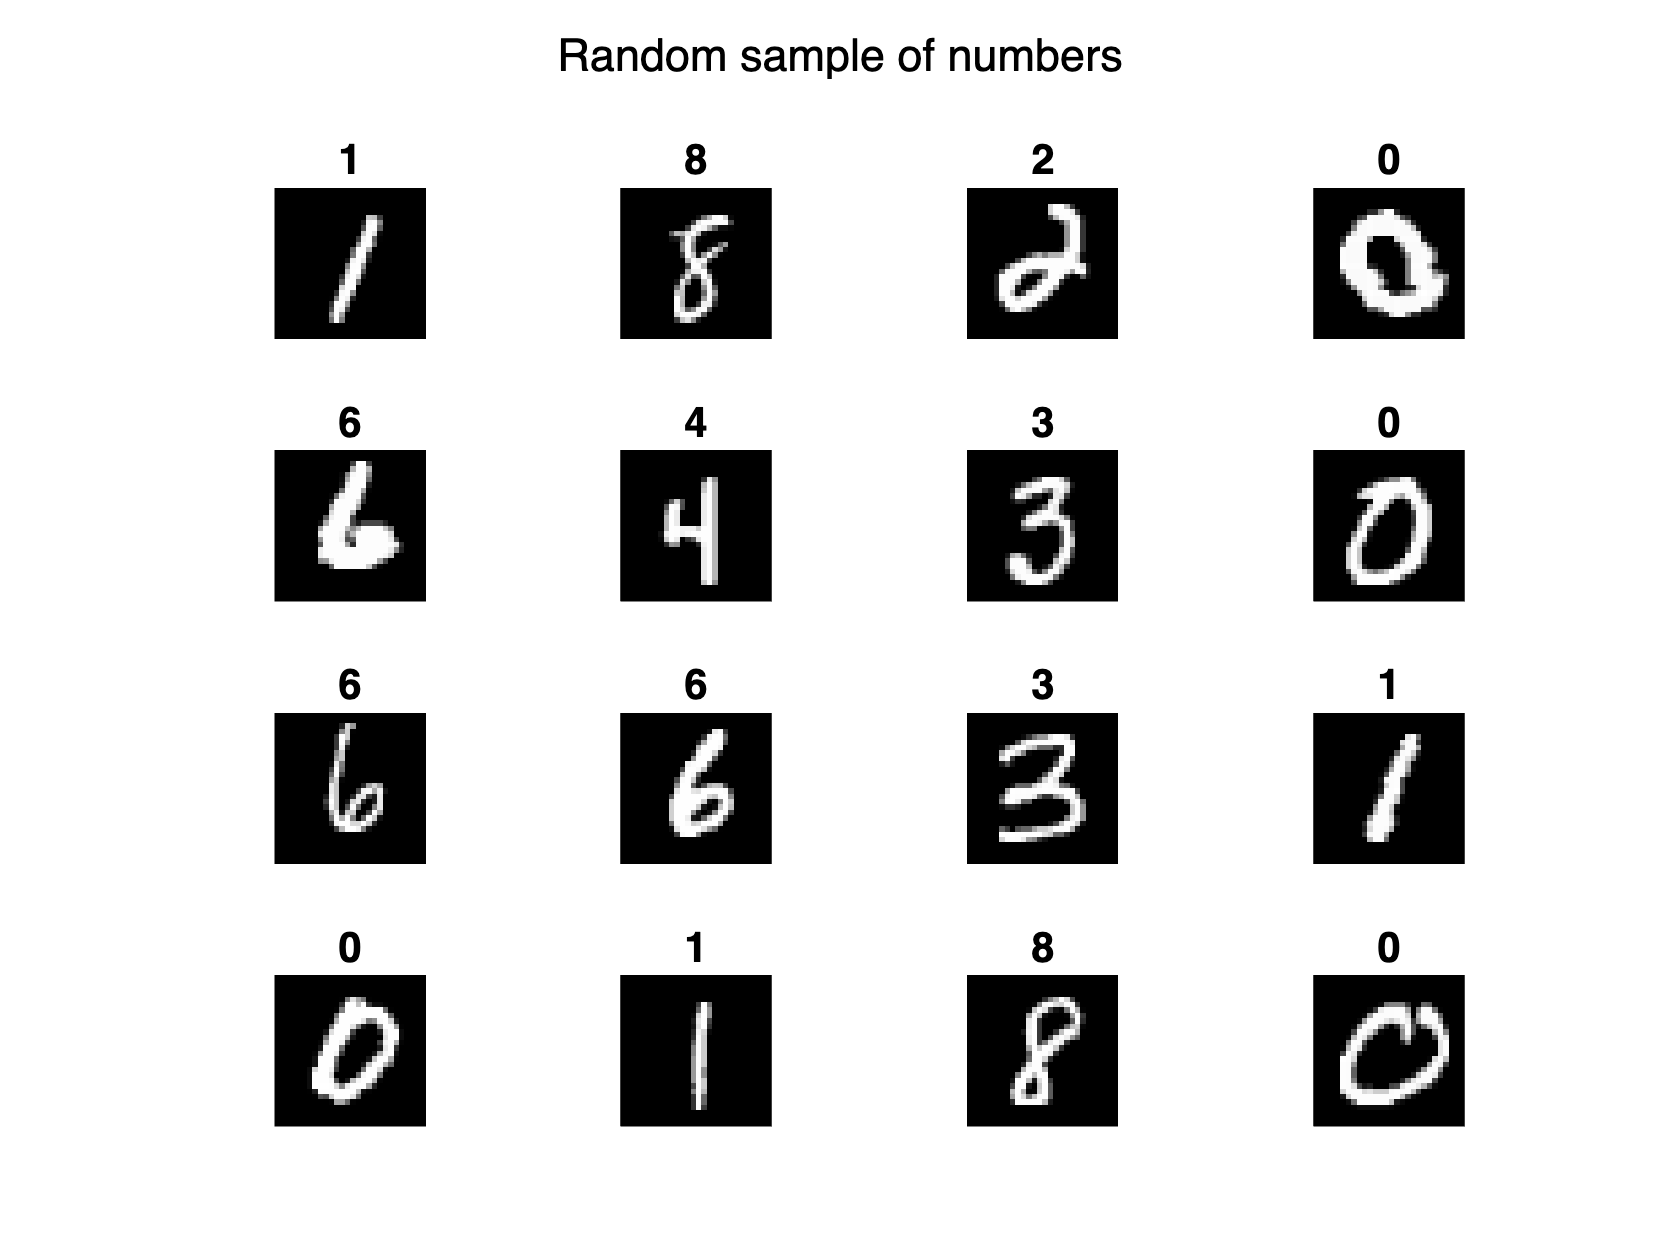

% illustration of n by n numbers
n = 4;
inds = randi(height(d),n^2,1);
for i = 1:n^2
    number = reshape(d{inds(i),2:end},28,28)';
    subplot(n,n,i);
    imshow(number,[0 255]);
    title(sprintf('%s',d{inds(i),1}),'FontSize',14)
end
sgtitle('Random sample of numbers');

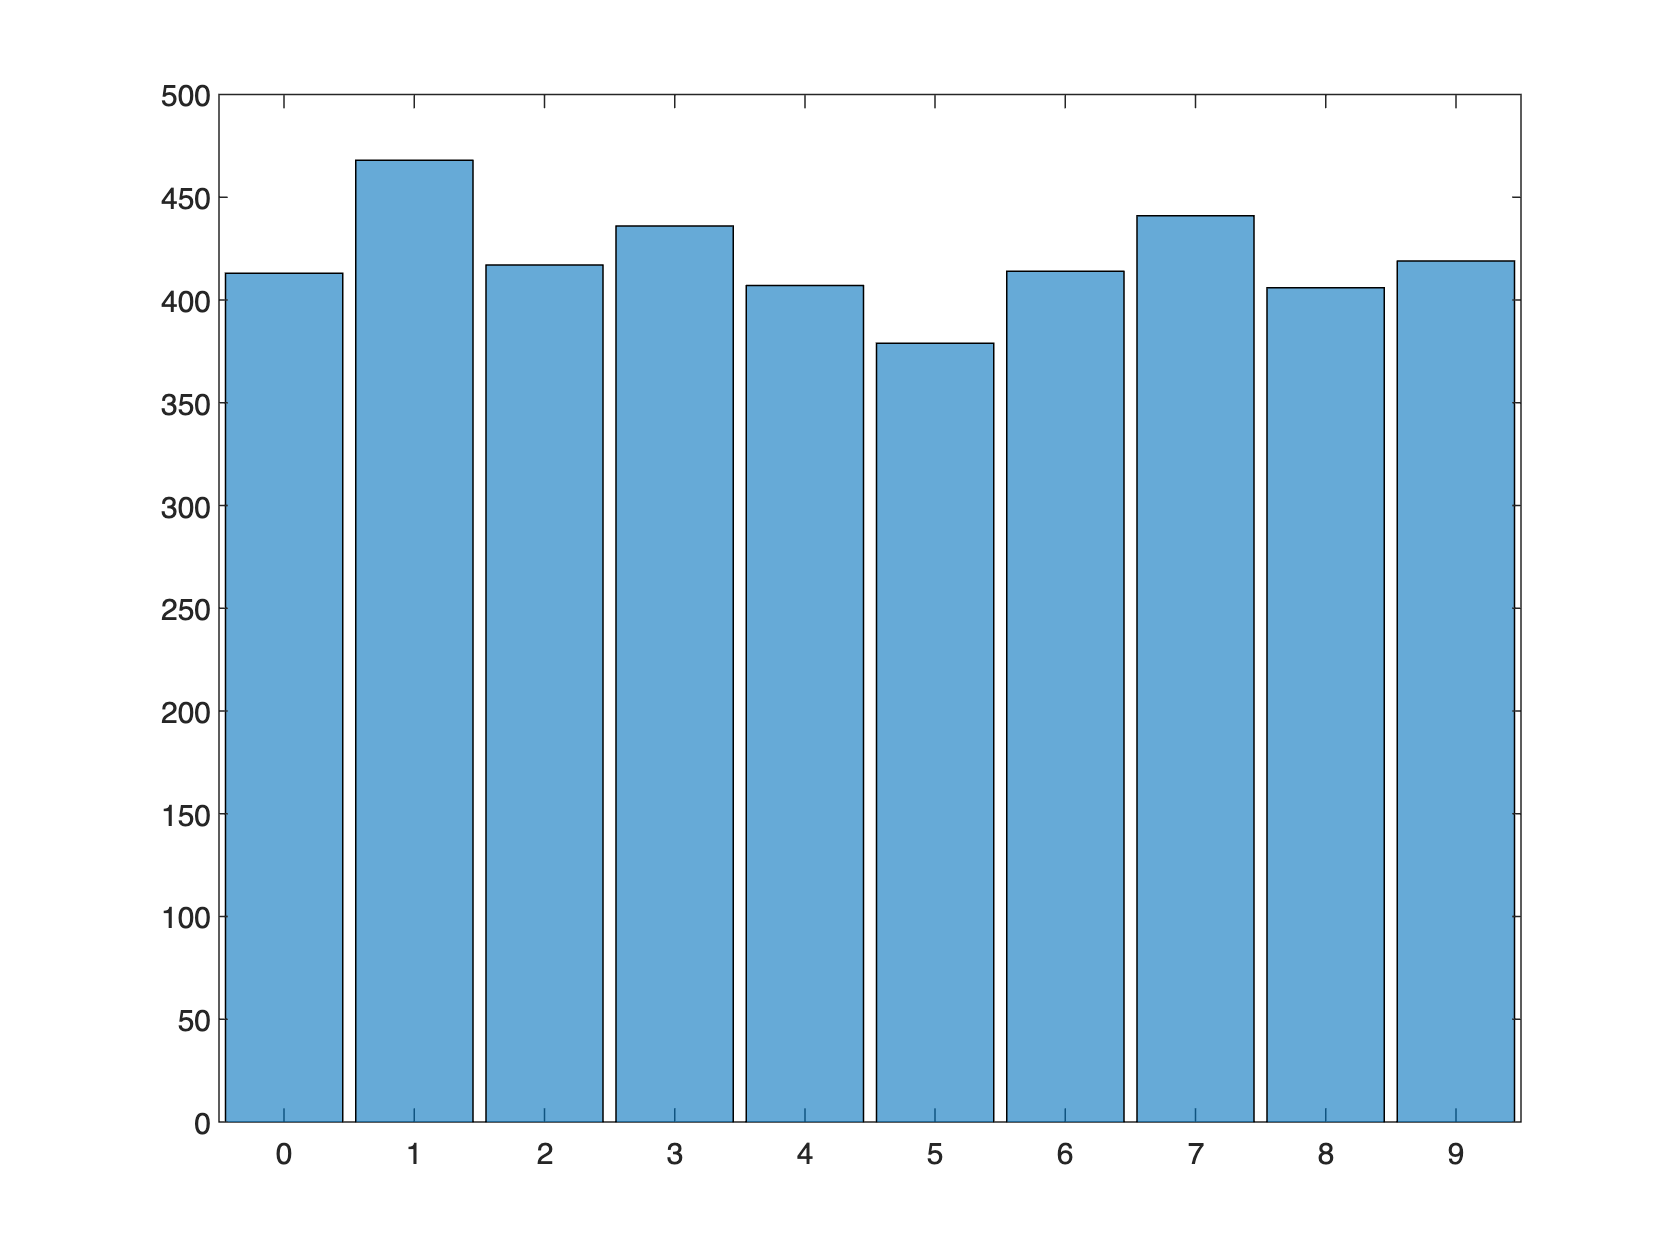

% class repartition
figure
histogram(d.label)

The dataset appears to be balanced.

% train the model with 5 neigbors
model = fitcknn(d(:,2:end),d.label,'NumNeighbors',5);
cvmodel = crossval(model);
kfoldLoss(cvmodel)

ans = 0.0798

% train the model with 5 neigbors but a different distance metric due to
% the size of the feature space
model = fitcknn(d(:,2:end),d.label,'NumNeighbors',5,'Distance','cosine');
cvmodel = crossval(model);
kfoldLoss(cvmodel)

ans = 0.0650

We can find the "best" settings for the model with Bayesian optimization. The basic is to build a probabilistic model of the objective function and then use this model to decide which hyperparameters to evaluate next. Specifically, Bayesian optimization maintains a posterior distribution over the objective function, which is updated after each evaluation of the function. The posterior distribution combines a prior distribution over the function with the likelihood of the observed data (i.e., the function values obtained by evaluating the hyperparameters).

The main advantage of Bayesian optimization is that it is able to balance exploration (trying new hyperparameters to improve the model) and exploitation (using the current best hyperparameters to obtain more accurate evaluations of the function). This is done by using an acquisition function, which measures the utility of evaluating a certain hyperparameter set based on the current posterior distribution. The acquisition function typically balances exploration and exploitation by trading off the expected improvement in performance and the uncertainty in the function evaluations.

%% find optimal value of k and distance metric
% hyperparameters
k = optimizableVariable('k',[3, 20], 'Type',"integer");
metric = optimizableVariable('metric',{'euclidean','cosine'}, 'Type',"categorical"); 
% repartition (5-fold cross validation)
p = cvpartition(d.label,"KFold",5)

p = K-fold cross validation partition
   NumObservations: 4200
       NumTestSets: 5
         TrainSize: 3360  3360  3360  3360  3360
          TestSize: 840  840  840  840  840
          IsCustom: 0

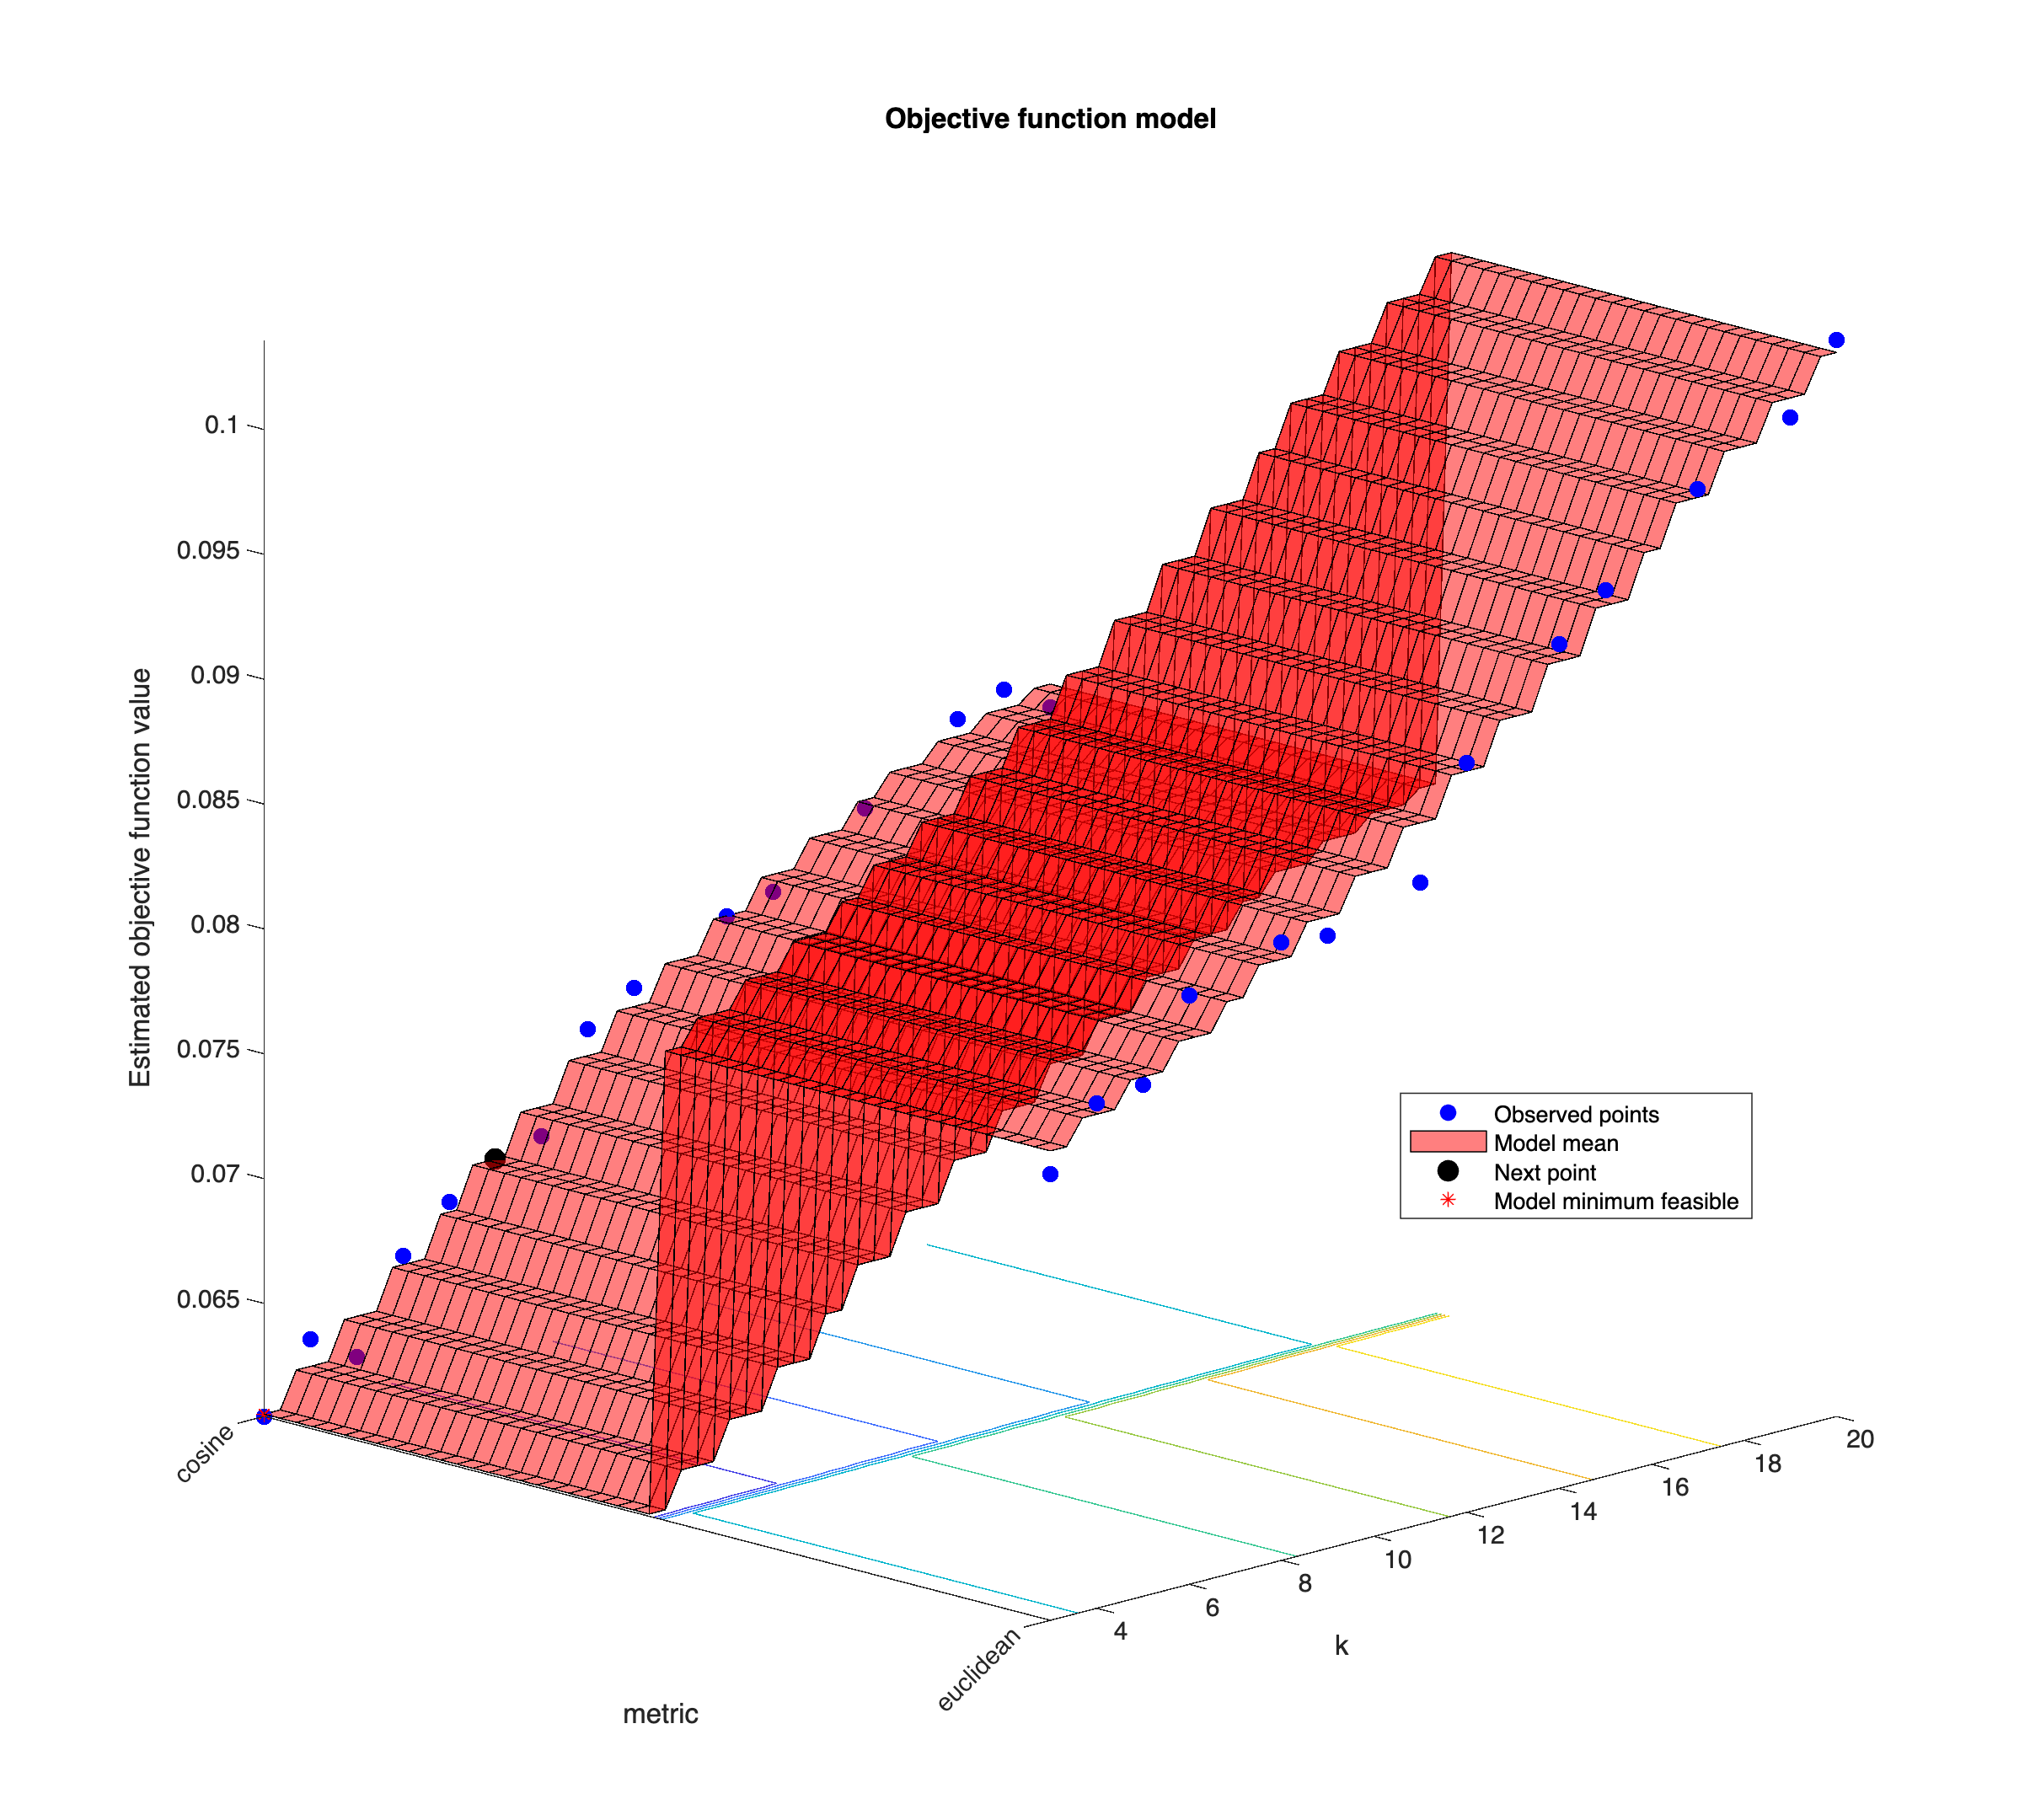

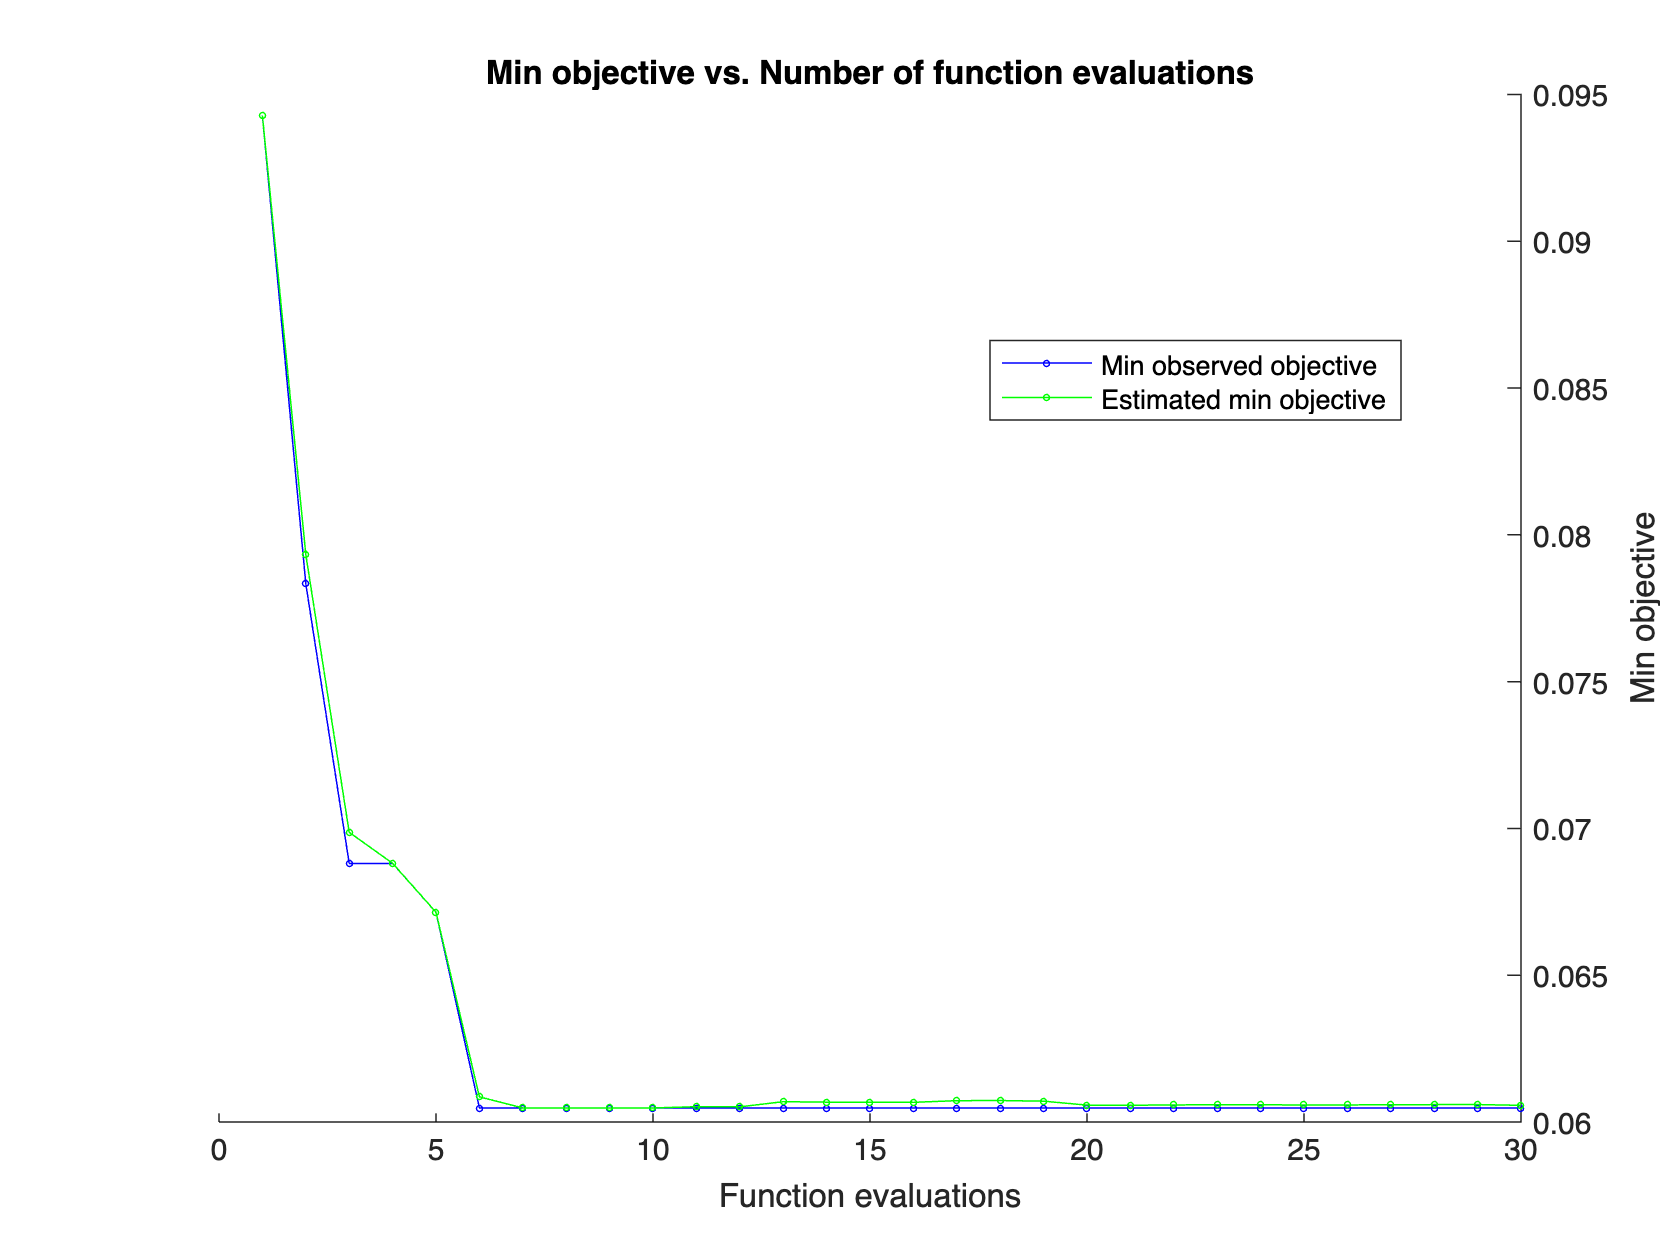

% function to optimise (i.e. find k that minimises the loss)
f = @(v) kfoldLoss(fitcknn(d(:,2:end),d.label,'CVPartition',p,'NumNeighbors',v.k,"Distance",char(v.metric)));
% actual optimisation
res = bayesopt(f,[k,metric],"Verbose",0);

res.MinObjective

ans = 0.0605

res.XAtMinObjective

ans = 1×2 table
    k    metric
    _    ______

    3    cosine


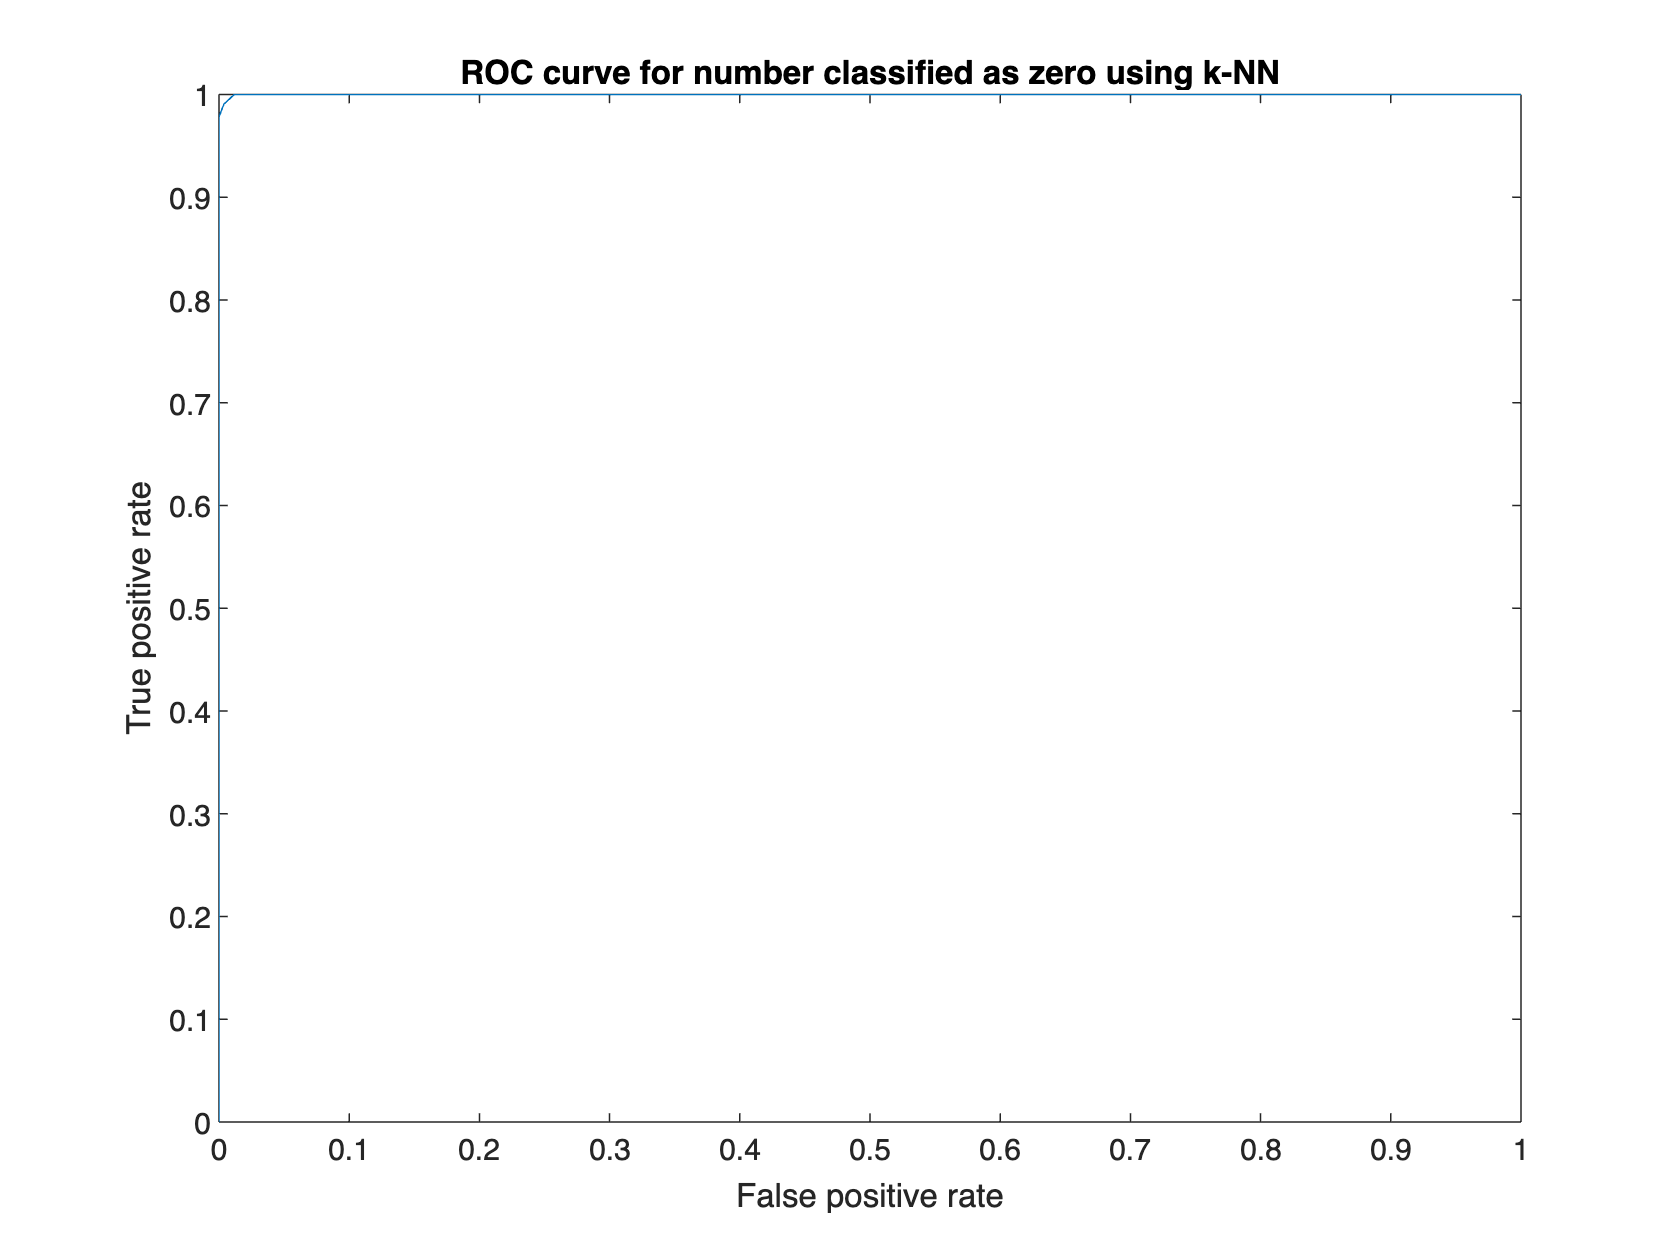

% model using the optimised hyperparameters
opt_model = fitcknn(d(:,2:end),d.label, 'NumNeighbors',res.XAtMinObjective.k, ...
                                        'Distance',char(res.XAtMinObjective.metric));
% model ROC curve for zero
[~,score] = resubPredict(opt_model);
[X,Y,T,AUC] = perfcurve(d.label,score(:,opt_model.ClassNames(1)),'0');
plot(X,Y)
title('ROC curve for number classified as zero using k-NN')
xlabel('False positive rate'); 
ylabel('True positive rate');

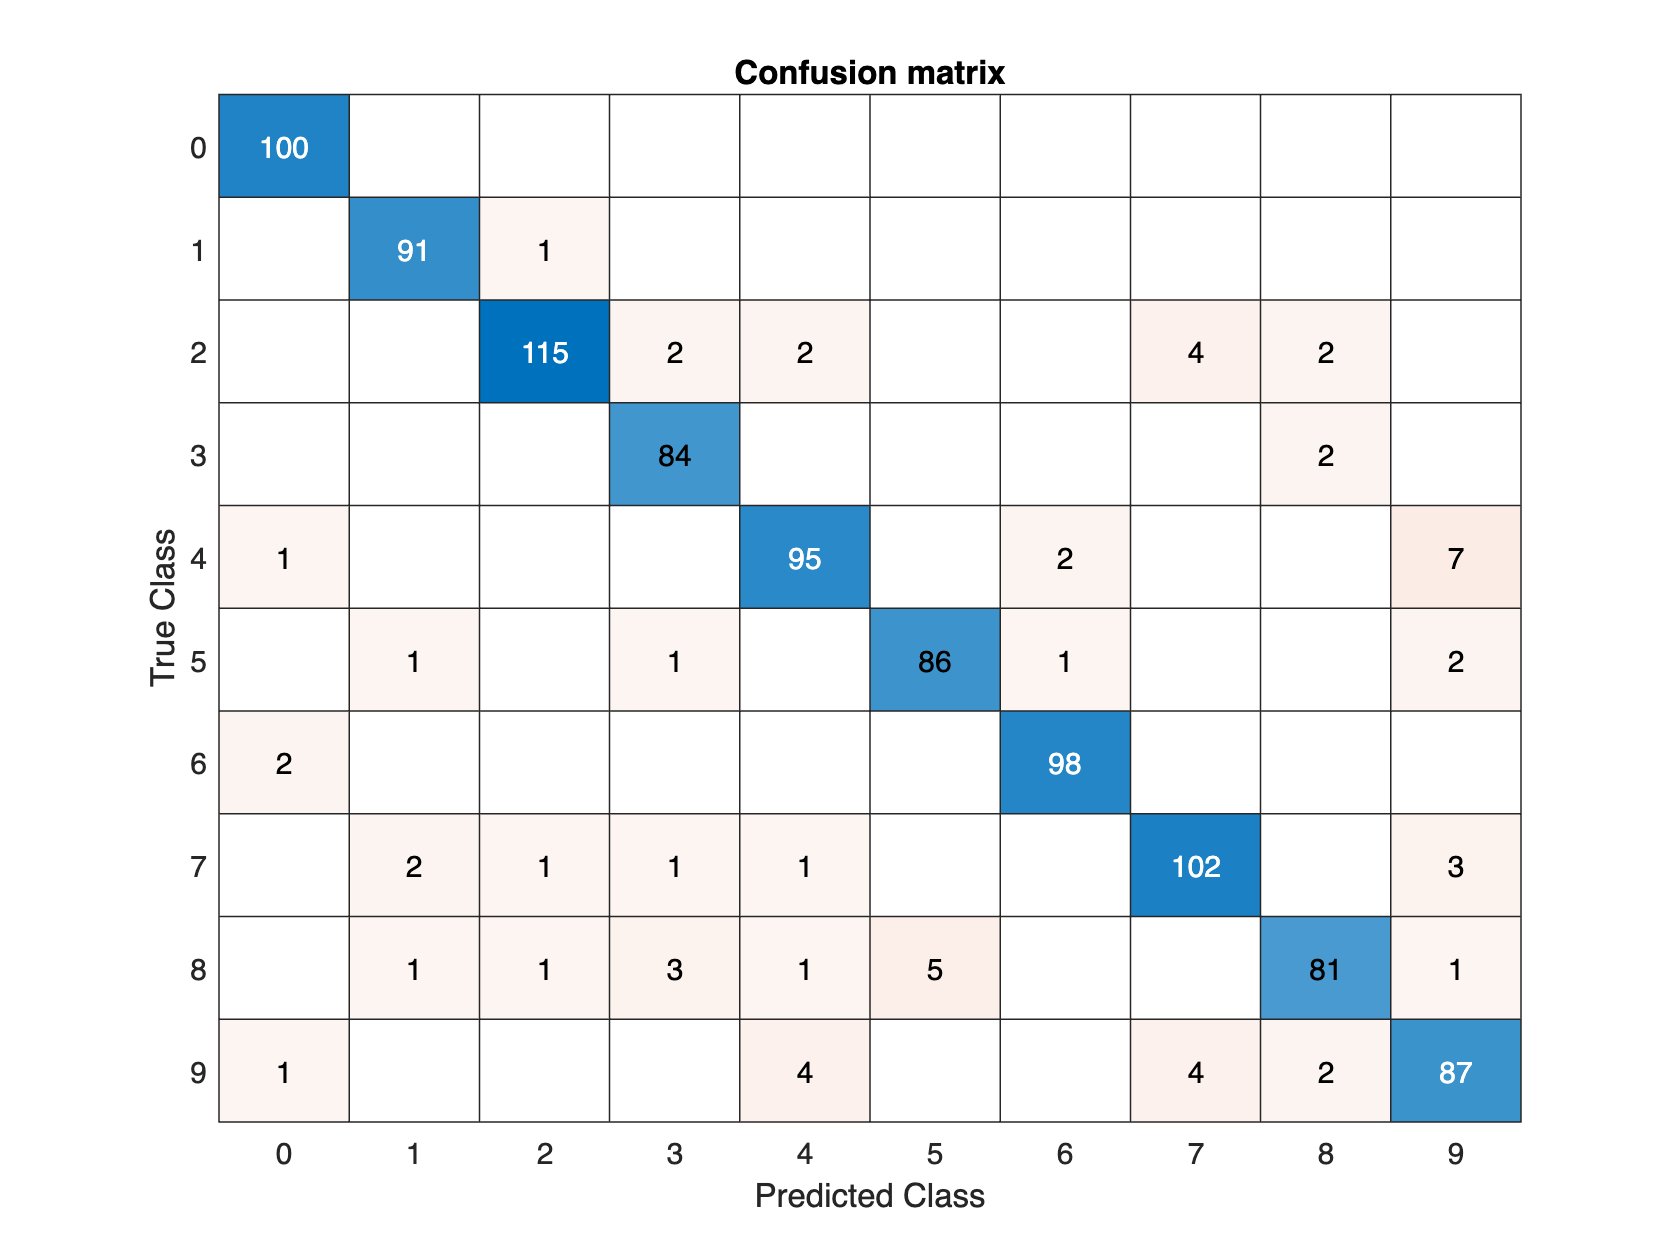

% confusion matrix for classification on validation data
pred = predict(opt_model , t(:,2:end));
confusionchart(t.label,pred)
title('Confusion matrix')

### Questions:

- Discuss some downsides of the euclidean distance and things you should consider when using it. Justifiy with a solid reasoning or illustrate it.

You can find additional information on distance metrics [here](https://www.mdpi.com/1099-4300/22/10/1105/htm).

# Naive Bayes classification

clear; close all force; clc

We have a look at the naive Bayes approach for supervised learning. The following topics will be adressed:

- the principle

- the importance of smoothing and hyperparameter tuning using the Laplace correction 

- how to deal with continuous variables

- the digits classification problem from the lectures.

- the text classification problem from the lectures.

## Principle

The file "golf.csv" contains some data on the meteorological conditions and whether or not a game of golf was played. The idea is to use a naive Bayes classifier to predict a decision.

d = readtable('./datasets/golf.csv');
% Set data types
d.Outlook = categorical(d.Outlook);
d.Temp = categorical(d.Temp);
d.Humidity = categorical(d.Humidity);
d.Windy = categorical(d.Windy);
d.Play = categorical(d.Play);
d

d = 14×5 table
    Outlook     Temp    Humidity    Windy    Play
    ________    ____    ________    _____    ____

    Rainy       Hot      High       FALSE    No  
    Rainy       Hot      High       TRUE     No  
    Overcast    Hot      High       FALSE    Yes 
    Sunny       Mild     High       FALSE    Yes 
    Sunny       Cool     Normal     FALSE    Yes 
    Sunny       Cool     Normal     TRUE     No  
    Overcast    Cool     Normal     TRUE     Yes 
    Rainy       Mild     High       FALSE    No  
    Rainy       Cool     Normal     FALSE    Yes 
    Sunny       Mild     Normal     FALSE    Yes 
    Rainy       Mild     Normal     TRUE     Yes 
    Overcast    Mild     High       TRUE     Yes 
    Overcast    Hot      Normal     FALSE    Yes 
    Sunny       Mild     High       TRUE     No  


Now we want to obtain the counts $C\left(F\left|Y\right.\right)$ for each feature, as we will be using these for the propability estimations. The tables below give you an overview of this

outlook = groupcounts(d,{'Play','Outlook'})

outlook = 5×4 table
    Play    Outlook     GroupCount    Percent
    ____    ________    __________    _______

    No      Rainy           3         21.429 
    No      Sunny           2         14.286 
    Yes     Overcast        4         28.571 
    Yes     Rainy           2         14.286 
    Yes     Sunny           3         21.429 


temp = groupcounts(d,{'Play','Temp'})

temp = 6×4 table
    Play    Temp    GroupCount    Percent
    ____    ____    __________    _______

    No      Cool        1         7.1429 
    No      Hot         2         14.286 
    No      Mild        2         14.286 
    Yes     Cool        3         21.429 
    Yes     Hot         2         14.286 
    Yes     Mild        4         28.571 


humidity = groupcounts(d,{'Play','Humidity'})

humidity = 4×4 table
    Play    Humidity    GroupCount    Percent
    ____    ________    __________    _______

    No       High           4         28.571 
    No       Normal         1         7.1429 
    Yes      High           3         21.429 
    Yes      Normal         6         42.857 


windy = groupcounts(d,{'Play','Windy'})

windy = 4×4 table
    Play    Windy    GroupCount    Percent
    ____    _____    __________    _______

    No      FALSE        2         14.286 
    No      TRUE         3         21.429 
    Yes     FALSE        6         42.857 
    Yes     TRUE         3         21.429 


Suppose we want to determine if (Sunny, Cool, High, False) are good conditions to play golf. 

- The likelihood of playing:$L(Play = Yes | Sunny, Cool, High, False)$

            
$$= P(Play = Yes) P(Sunny|Play = Yes) P(Cool|Play = Yes)P(High|Play = Yes)P(Windy|Play = Yes) $$


            
$$= \frac{9}{14} \frac{3}{9} \frac{3}{9} \frac{3}{9} \frac{6}{9} = 0.01587301587$$


- The likelihood of not playing: $L(Play = No | Sunny, Cool, High, False)
$

            
$$= P(Play = No) P(Sunny|Play = No) P(Cool|Play = No)P(High|Play = No)P(Windy|Play = No)$$


            
$$= \frac{5}{14}  \frac{2}{5} \frac{1}{5} \frac{4}{5} \frac{2}{5} = 0.009142857143$$


After normalizing the likelihoods we obtain the probalilities and can observe that we should play:

    
$$P(Play = Yes | Sunny, Cool, High, False) = 0.63$$


    
$$P(Play = No | Sunny, Cool, High, False) = 0.37$$


In Matlab we can implement this either by coding it directly, or by using the Classification Learner App. As we are working with categorical variables for the predictors, a multivariate multinomial (mvmn) distribution is used for the values of the predictors. NaNs are removed.

model = fitcnb(d,"Play")

model =   ClassificationNaiveBayes
            PredictorNames: {'Outlook'  'Temp'  'Humidity'  'Windy'}
              ResponseName: 'Play'
     CategoricalPredictors: [1 2 3 4]
                ClassNames: [No    Yes]
            ScoreTransform: 'none'
           NumObservations: 14
         DistributionNames: {'mvmn'  'mvmn'  'mvmn'  'mvmn'}
    DistributionParameters: {2×4 cell}
         CategoricalLevels: {[3×1 double]  [3×1 double]  [2×1 double]  [2×1 double]}


  Properties, Methods


loss(model, d)

ans = 0.0714

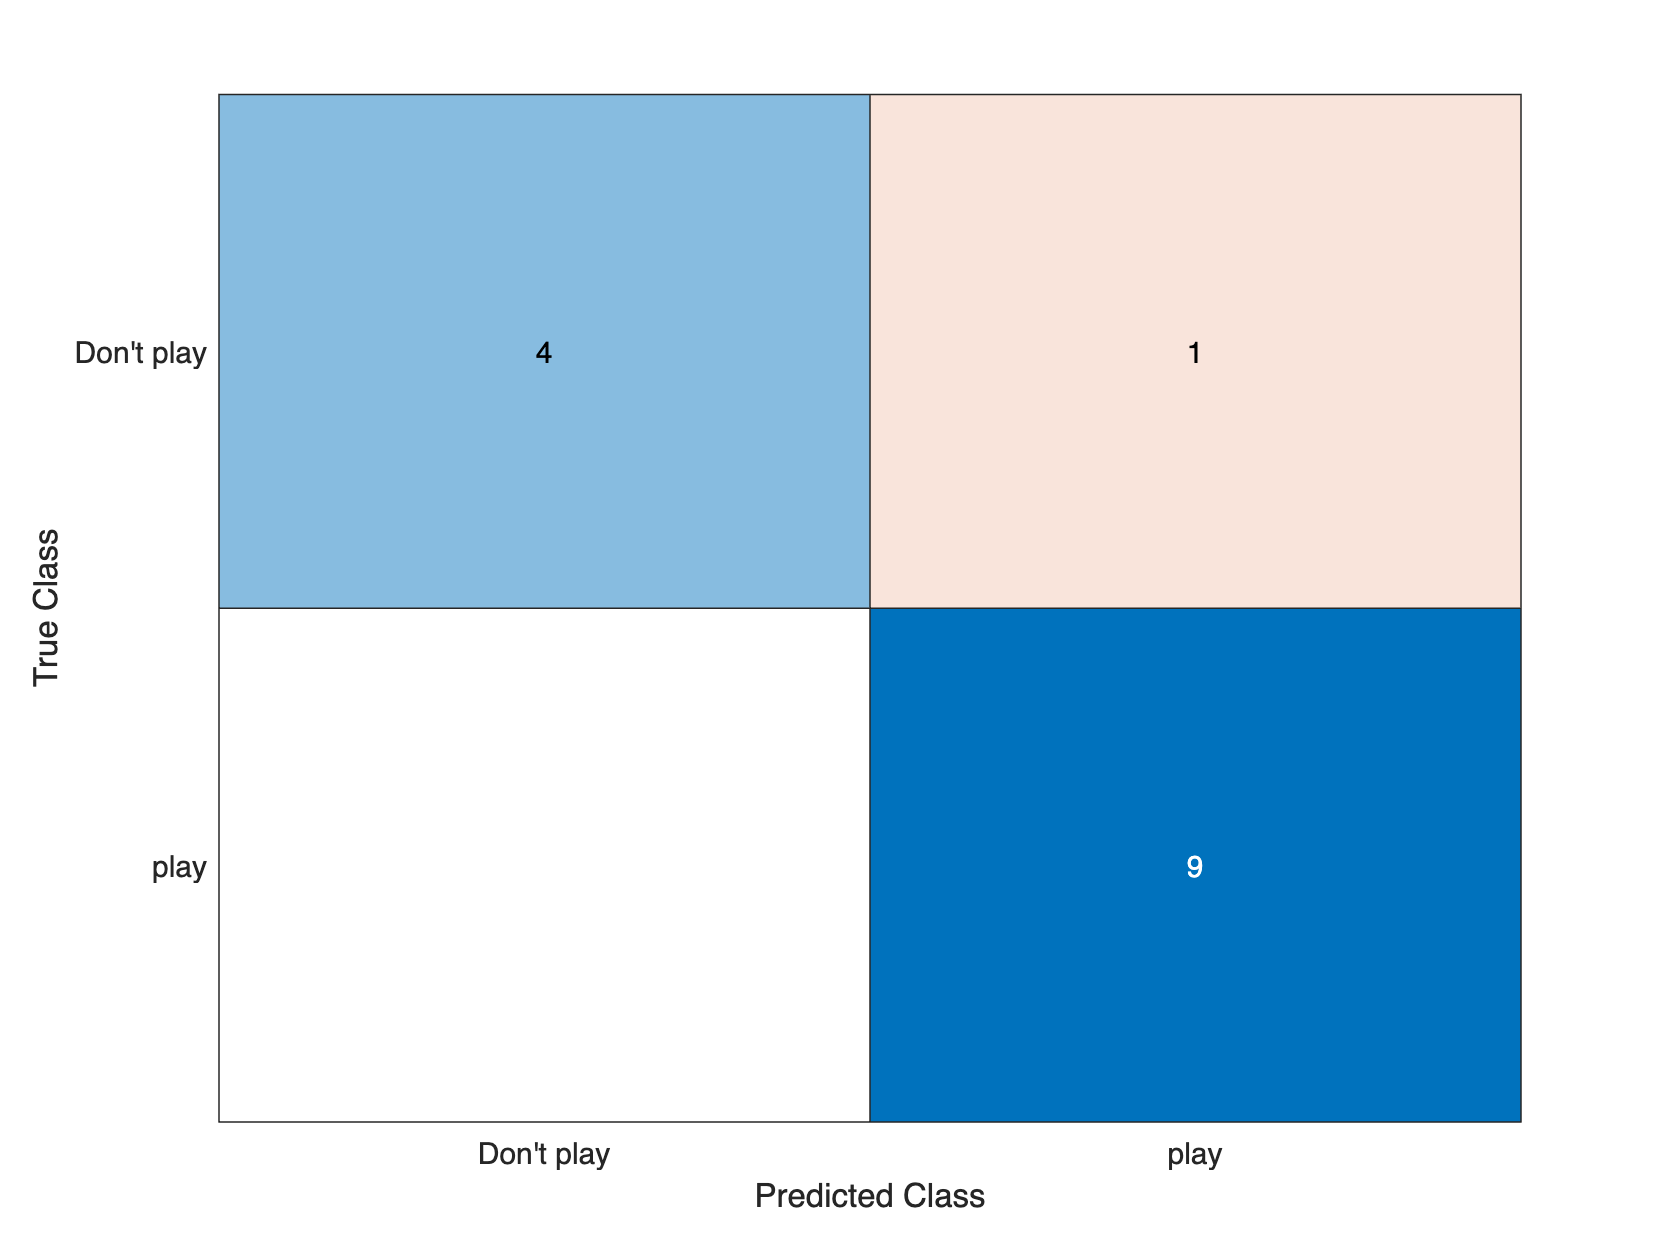

cm = confusionmat(d.Play, predict(model, d));
confusionchart(cm, ["Don't play","play"])

## Additive smoothing

You may have noticed that there is one entry that is not present in the training data (no play with overcast weather), this might lead to a false conclusion that you will allways play when the weather is overcast, although this may not correct at all. 

- What is the prediction of an entry with overcast weather? 

- Can you explain the parameters of the models' distributions? 

- What would be the impact of increasing the value of the smoothing factor to $+\infty$?

evaloutlook = categorical(["Overcast"; "Overcast";"Overcast"]);
evaltemp = categorical(["High"; "Cool";"Mild"]);
evalhumidity = categorical(["high";"normal";"High"]);
evalwindy = categorical(["TRUE"; "FALSE";"TRUE"]);
t = table(evaloutlook, evaltemp, evalhumidity, evalwindy,'VariableNames',{'Outlook','Temp','Humidity','Windy'})

t = 3×4 table
    Outlook     Temp    Humidity    Windy
    ________    ____    ________    _____

    Overcast    High     high       TRUE 
    Overcast    Cool     normal     FALSE
    Overcast    Mild     High       TRUE 


predict(model,t)

ans = 3×1 categorical array
     Yes 
     Yes 
     Yes 


% model priors
model.Prior

ans =     0.3571    0.6429


% distributions for each feature:
% 1xN_features
model.DistributionNames

ans = 1×4 cell array
    {'mvmn'}    {'mvmn'}    {'mvmn'}    {'mvmn'}


% parameters for each distribution
model.DistributionParameters

ans = 2×4 cell array
    {3×1 double}    {3×1 double}    {2×1 double}    {2×1 double}
    {3×1 double}    {3×1 double}    {2×1 double}    {2×1 double}


### Question(s):

- Retrace these values to make sure you understand the principle.

## Continuous data

In the previous example, all data was discrete. We will now take a look at how we can deal with continuous data when using the naive bayes approach. We will be using the Iris dataset. This data set has four continuous features (sepal length and width + petal length and width) for three variants of Iris flowers. 

It is clear that we can no longer use counts as tool to predict probabilities. What is typically done in the case of continuous features, is to assume a gaussian distribution and use the probaility density function (pdf) for the likelihood. 

Suppose we want to determine $P(x|Y=\text{Iris-setosa})$for the feature sepal_length. If we assume a gaussion distrubution, the pdf is given by:

   
$$f_{sepal\_length}(x) = \frac{1}{\sqrt{2\pi\sigma_{sepal\_length}}} e^{\frac{-(x-\mu_{sepal\_length})^2}{2\sigma^2_{sepal\_length}}}$$


So all we need to do is calculate the conditional $\mu$ and $\sigma$ for each feature. This gives us the distribution the we will be using to calculate the likelihoods.

clear; close all force; clc
% load data
load fisheriris
model = fitcnb(meas,species,"PredictorNames",["sepal length", "sepal width", "petal length", "petal width"],...
        "ResponseName",'Iris species')

model =   ClassificationNaiveBayes
            PredictorNames: {'sepal length'  'sepal width'  'petal length'  'petal width'}
              ResponseName: 'Iris species'
     CategoricalPredictors: []
                ClassNames: {'setosa'  'versicolor'  'virginica'}
            ScoreTransform: 'none'
           NumObservations: 150
         DistributionNames: {'normal'  'normal'  'normal'  'normal'}
    DistributionParameters: {3×4 cell}


  Properties, Methods


loss(model, meas, species)

ans = 0.0400

## Spam detection

You are given a dataset  with regard to email spam. This is the same dataset that was referred to during the lectures. Given that the collection of non-spam e-mails came from filed work and personal e-mails, the word 'george' and the area code '650' are indicators of non-spam.  These are useful when constructing a personalized spam filter.  There are 4601 entries (Spam: 1813  (39.4%) - Non-Spam  2788  (60.6%)), and a total of 58 attributes (57 continuous, 1 nominal class label).

Structure of the data:

- The last column denotes whether the e-mail was considered spam (1) or not (0), i.e. unsolicited commercial e-mail.  

- Most of the attributes indicate whether a particular word orcharacter was frequently occuring in the e-mail:  48 continuous real [0,100] attributes of type word_freq_WORD = percentage of words in the e-mail that match WORD,i.e. 100 * (number of times the WORD appears in the e-mail) / total number of words in e-mail.  A "word" in this case is any string of alphanumeric characters bounded by non-alphanumeric characters or end-of-string.

- 6 continuous real [0,100] attributes of type char_freq_CHAR = percentage of characters in the e-mail that match CHAR, i.e. 100 * (number of CHAR occurences) / total characters in e-mail

- The run-length attributes (55-57) measure the length of sequences of consecutive capital letters.  

- capital_run_length_average = average length of uninterrupted sequences of capital letters

- capital_run_length_longest = length of longest uninterrupted sequence of capital letters

- capital_run_length_total = sum of length of uninterrupted sequences of capital letters = total number of capital letters in the e-mail

- Missing Attribute Values: None

As you can see from the above describtion you have an interesting combination of features. You have the basic word frequency, but also genererated features such as the number of capital letters etc. It is up to you to make good use of these. An interesting sidenote to keep in mind: false positives (marking good mail as spam) are very undesirable when building a spam filter, as this could have you overlook important emails.

clear; close all force; clc
% load data
d = readtable('./datasets/spambase.csv');

% Set data types
d.label = categorical(d.label, [0 1], {'ham', 'spam'});
summary(d.label)

     ham       2788 
     spam      1813 


Note the the data in not perfectly partitioned in a 50-50 ratio between 'spam' & 'ham'.  We wil account for this by using stratified sampling.

% split the data for 10-fold cross validation using stratified sampling
% (i.e. we try to avoid biased training by using optimal sample distribution)
C = cvpartition(d.label,'kfold',10)

C = K-fold cross validation partition
   NumObservations: 4601
       NumTestSets: 10
         TrainSize: 4141  4140  4141  4141  4141  4141  4141  4141  4141  4141
          TestSize: 460  461  460  460  460  460  460  460  460  460
          IsCustom: 0

Let's build a model using all of the features combined with k-fold cross validation

% naive bayes model using multivariate normal distribution
nbmodel = fitcnb(d,"label");
% explain the warning if it occurs
model = crossval(nbmodel,'CVPartition', C);

% k-fold accuracy:
1 - kfoldLoss(model)

ans = 0.8201

### Feature selection

For many data sets with a large number of features and a limited number  of observations, usually many features are not useful for producing a desired learning result and the limited observations may lead the learning algorithm to overfit to the noise.  Reducing features can also save storage and computation time and  increase comprehensibility. This might also be the case for our analysis. 

Feature selection can be done in different ways. Some options that you already know from your statistics course are forward selection, stepwise regression & backward elemination. Below you can find an illustration of this. First we partition the data in a training and testing subset. The feature selection procedure performs a sequential search on each candidate feature. The misclassification error is used as the performance indicator for that subset. The training set is used to select the features and to fit the model,  while the test set is used to evaluate the performance of the finally  selected feature.

%% apply forward selection on features
% data & labels, converted to matrices for sequentialfs
X = d{:,1:end-1} + rand(size(d{:,1:end-1}))*1e-12;
Y = d{:,end};
% actual feature selection
opt = statset('display','iter','UseParallel',true);
[featsel, hist] = sequentialfs(@(xt,yt,xte,yte) nbeval(xt,yt,xte,yte), X,Y,'cv', C,'options', opt);

Start forward sequential feature selection:
Initial columns included:  none
Columns that can not be included:  none
Step 1, added column 53, criterion value 0.258205
Step 2, added column 30, criterion value 0.214084
Step 3, added column 52, criterion value 0.185612
Step 4, added column 12, criterion value 0.160183
Final columns included:  12 30 52 53 


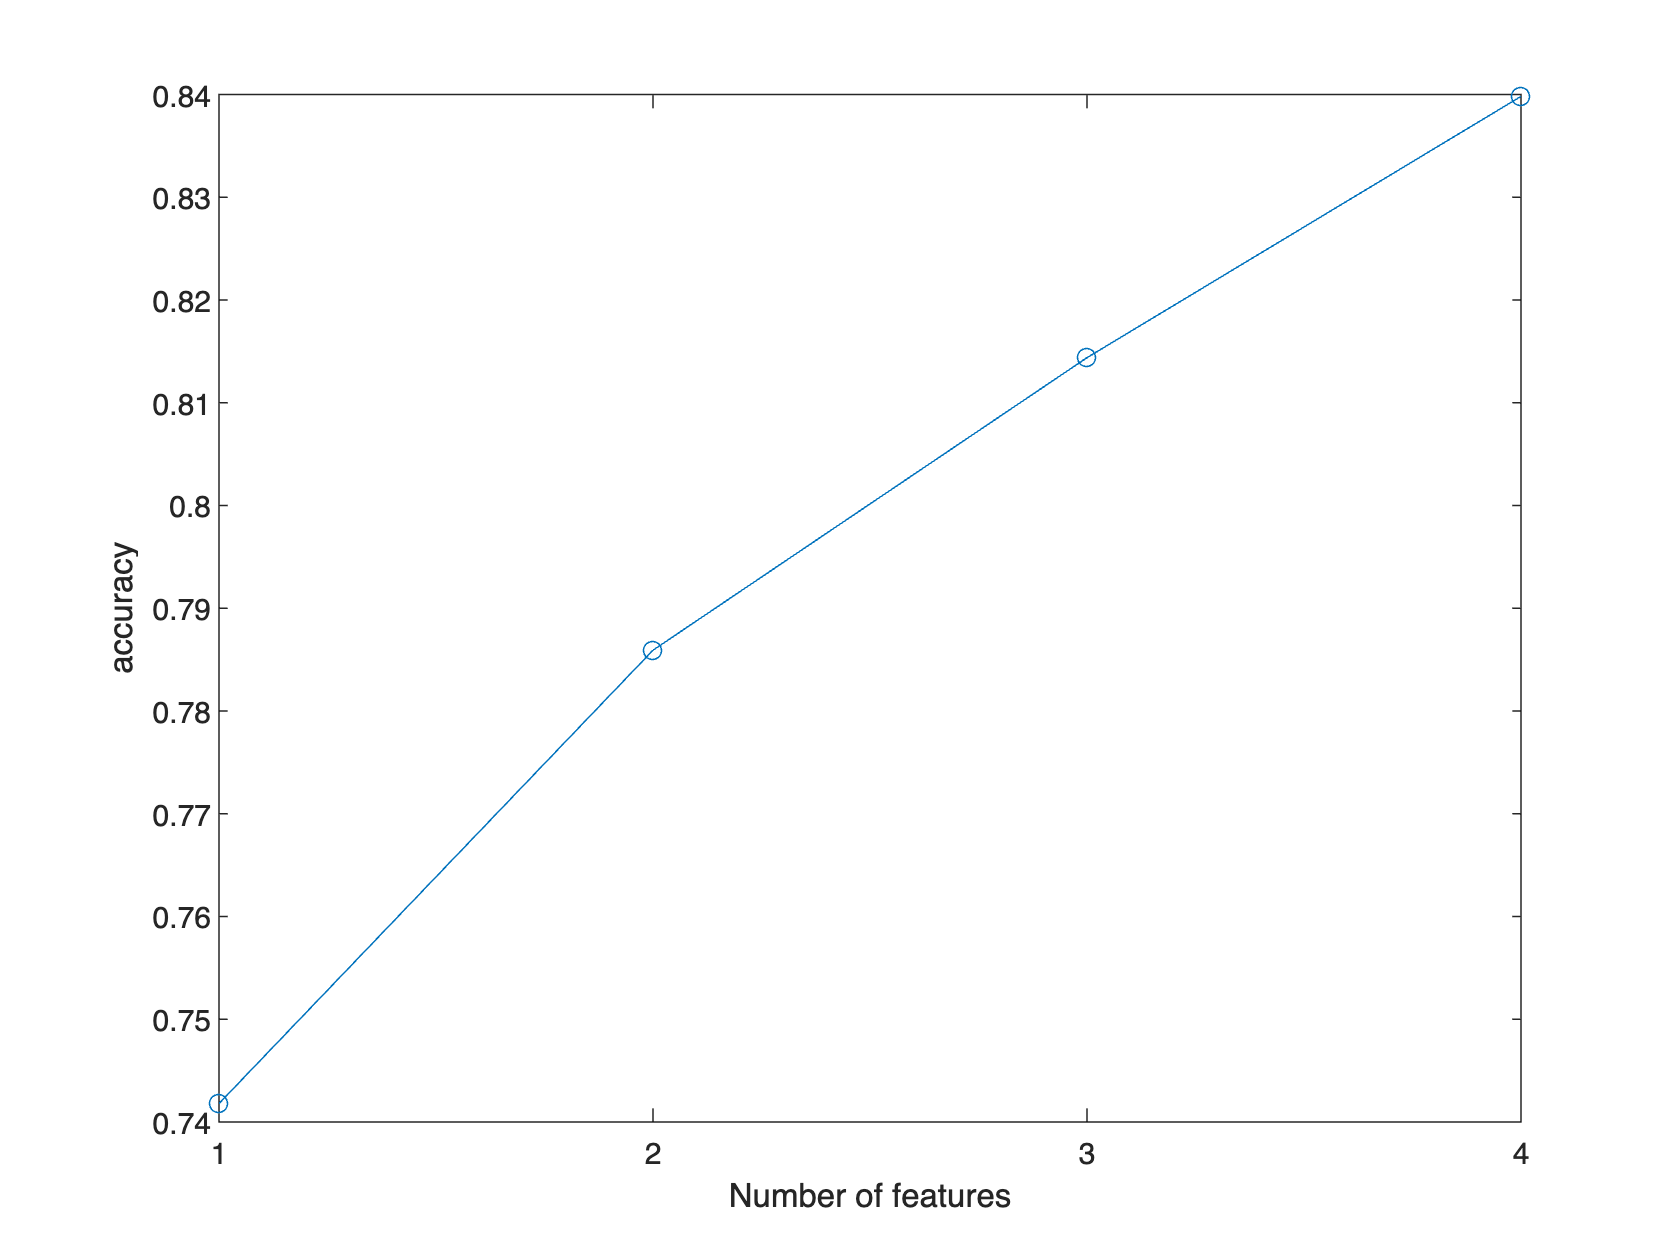

% Illustrate accuracy evolution
plot(1 - hist.Crit,'-o')
xlabel("Number of features")
xticks(1:length(hist.Crit))
ylabel("accuracy")

fprintf('retained features: %s',string(join(d.Properties.VariableNames(featsel),', ')));

retained features: word_freq_will, word_freq_labs, char_freq___3, char_freq___4

Now that we have a list of selected features, we can use them to obtain a more performant model.

% Train model with selected features:
optimodel = fitcnb(X(:,featsel),Y);
% explain the warning if it occurs
optimodel = crossval(optimodel);
% k-fold accuracy:
1 - kfoldLoss(optimodel)

ans = 0.8027

By default the above method is a lazy method, as it will stop as son as there is no improvement. However, as you can see below, adding additional features leads to a significant improvement, with an accuracy around 88%, a big difference with the model that includes all data and only reaches 82%.

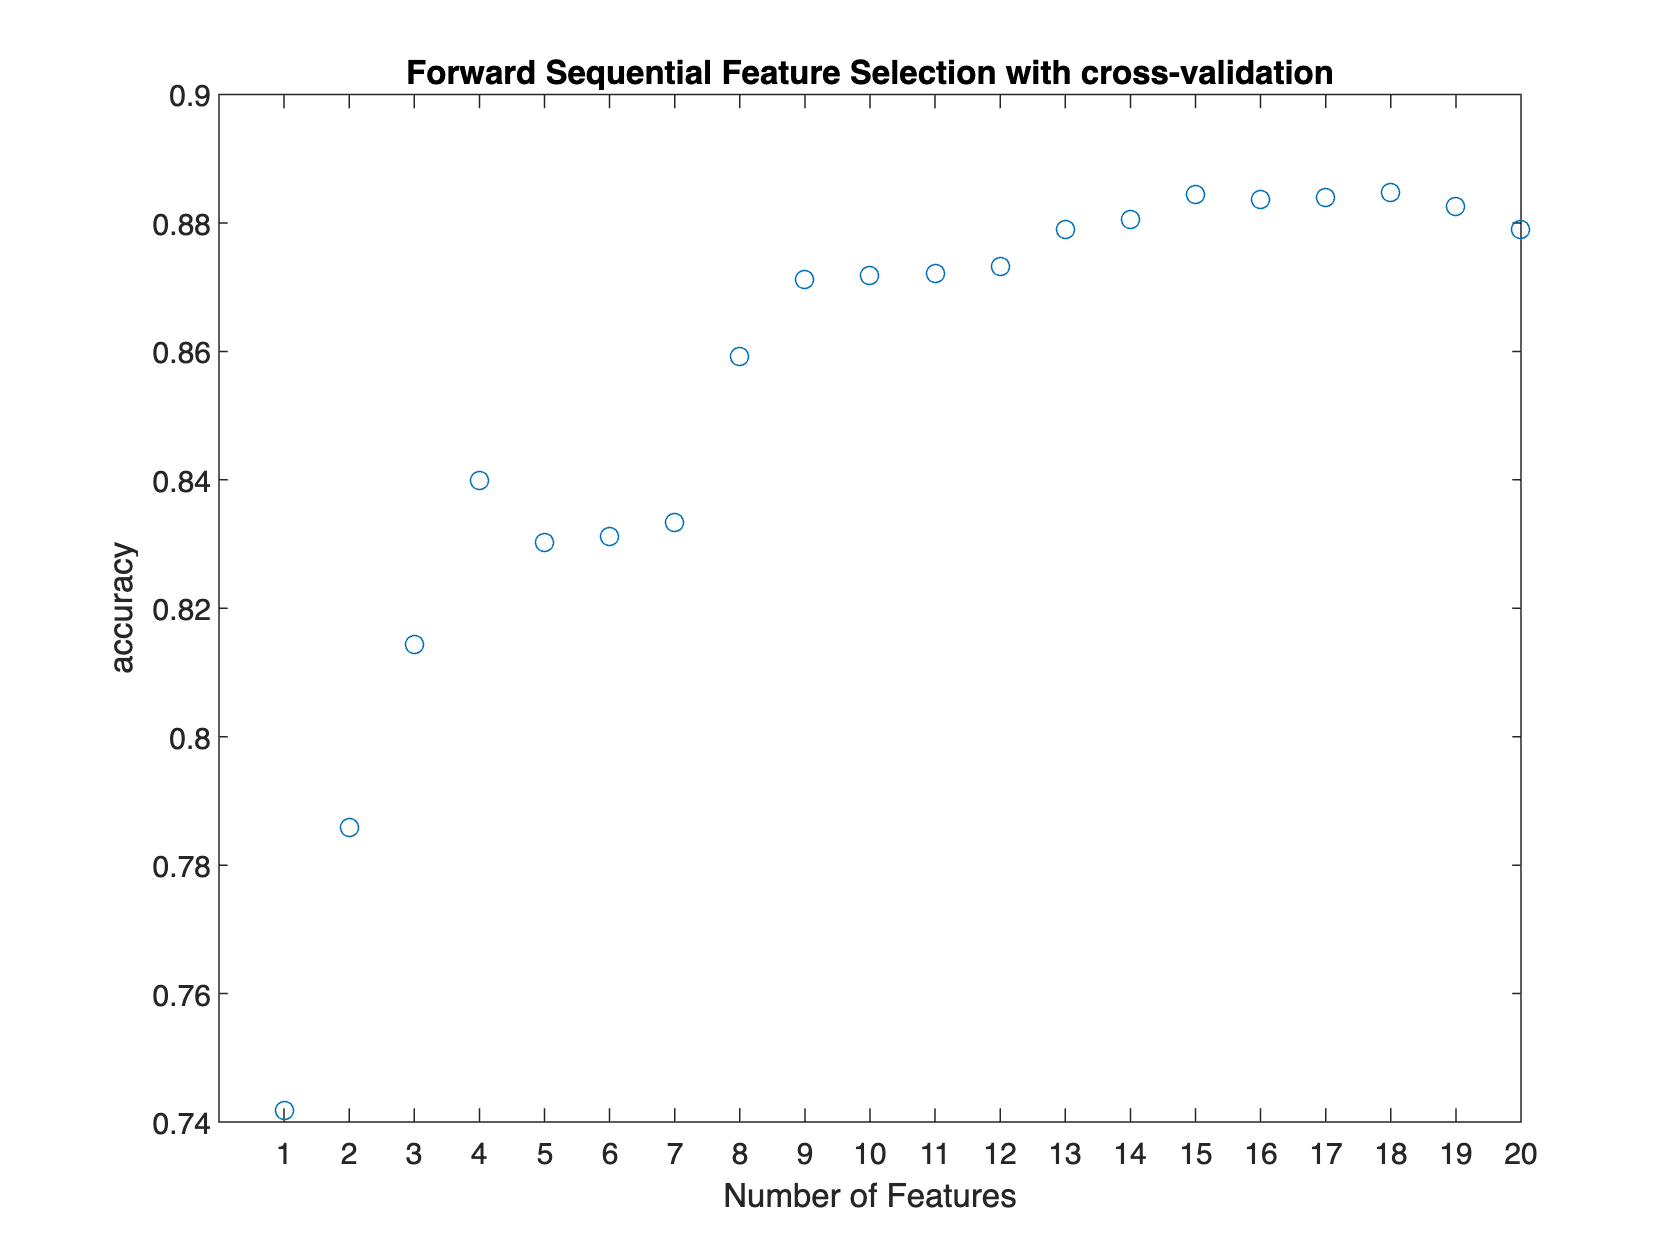

% illustration of adding more features
[fsfor,historyCV] = sequentialfs(@(xt,yt,xte,yte) nbeval(xt,yt,xte,yte),X,Y,'cv',C,'nfeatures',20);
plot(1-historyCV.Crit,'o');
xlabel('Number of Features');
ylabel('accuracy');
xticks(1:length(historyCV.Crit))
title('Forward Sequential Feature Selection with cross-validation');

function res = nbeval(xtrain,ytrain, xtest, ytest)
    % NBEVAL helper function to train a Naive-Bays model. Returns the
    % number of mismatches

    % build model using training data
    model = fitcnb(xtrain, ytrain);
    % apply model on testin data
    y_pred = predict(model, xtest);
    % count mismatches
    res = sum(~(y_pred == ytest));
end